# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# FULL WRITTEN EXAMINATION -  A.Y. 2023/2024

**February 3, 2025**

# PART 2 - Design of a Controller for an Unstable System - A Dual-Loop Control Scheme

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure 

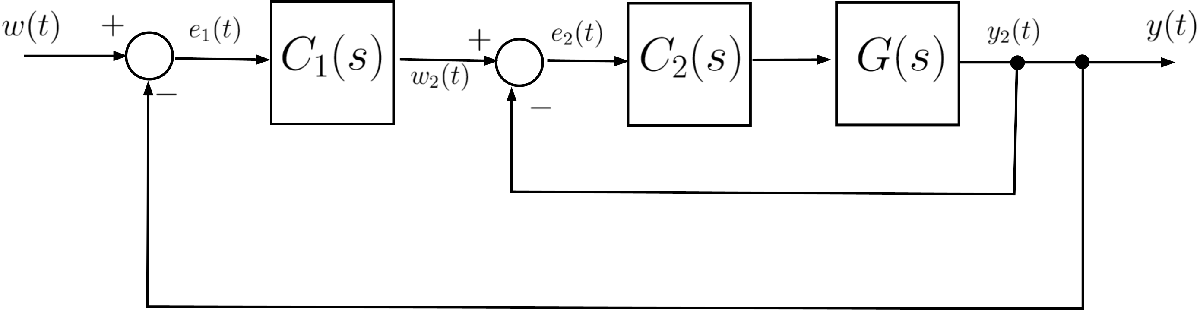	

where $G(s)$ is given by                


$$G(s) = 4.8 \frac{(1+0.15\,s)}{(1-0.15\,s)}$$


You may refer to the Example 3 in slides 41-44 of Part 10 of the lecture handouts.				

### Assignment 		

**A1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- The crossover angular frequency satisfies $\omega_c \ge 10\;\text{rad/s}$; 

- The phase margin satisfies $\varphi_m \ge 60^{\degree}$.

- Finally, $G(s)$ is not a strictly proper transfer function, but both the controller $C(s)$ and the open-loop $L(s)$ transfer functions have to be strictly proper.

As usual, $\mathbf{1}(t)$ denotes the unit step function: $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 1
\end{array} \right.$ 

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

Since the system is open-loop unstable, the Bode stability criterion cannot be used in the way that is usual for the loop-shaping approach to the design of the controller for minimum-phase systems. Hence, as suggested in Example 3 in slides 41-44 of Part 10 of the lecture handouts, we use a **dual-loop control scheme**, as shown in the Figure below 

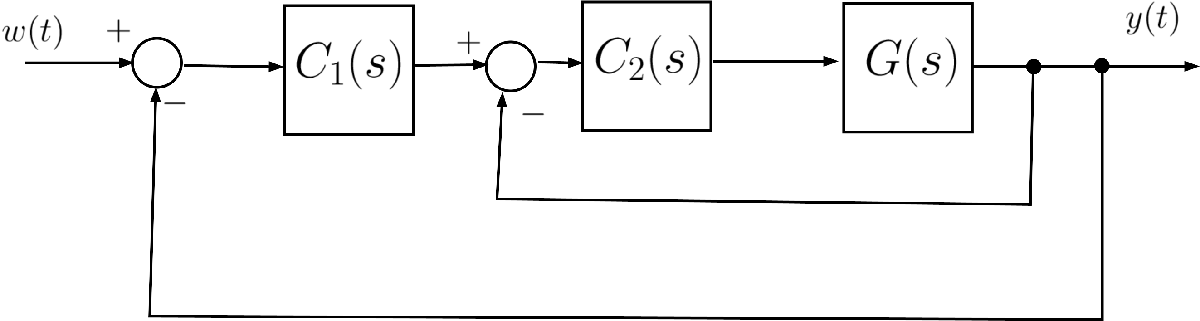

The design of the controller $C(s)$ is carried out by the following logical steps:

- The controller $C_2(s)$ is designed so as the **inner-loop transfer function **$F_2(s)$ from the output of the block $C_1(s)$ is **asymptotically** **stable**.

-  Subsequently, $C_1(s)$ will be designed to meet the other requirements.

### Stabilisation of the Inner Loop

#### Design of the Inner Loop Controller

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 4.8*(1+0.15*s)/(1-0.15*s); % the unstable process G(s)

**First Trial**: To design the inner asymptotically-stable loop, the first attempt is to set


$$C_2(s) = \mu_2,\; \mu_2 \in \mathbb{R}$$


**First Approach**: Apply the **Routh-Hurwitz criterion. **$C_2(s) = \mu_2 \; \Longrightarrow \; L_2(s) = 4.8 \,\mu_2\,\frac{(1+0.15\,s)}{(1-0.15\,s)} \; \Longrightarrow \; 1+L_2(s)=0 \,\longleftrightarrow\,
0.15\,\left(4.8\,\mu_2-1\right)\,s + \left(4.8\,\mu_2+1\right)=0=0
$

Thus, we obtain the following conditions:

- if $\mu_2<-\frac{5}{24}$ or $\mu_2>+\frac{5}{24}$ then the inner loop is asymptotically stable;

- if $\mu_2 \in \left(-\frac{5}{24}\;,\quad +\frac{5}{24}\right)$, the inner loop is unstable;

- if $\mu_2 =  -\frac{5}{24}$, the inner loop is marginally stable;

- $\mu_2 =  +\frac{5}{24}$ is a not admissible condition.

All values $\left\vert\mu_2 \right\vert>+\frac{5}{24}$ are feasible: the goal is merely to stabilise the inner-loop system. In this respect, a possible attempt is to set $\mu_2=+10$.

**Second Approach**:** Analyse the** **Root Locus**. 

Let's explore the Root Locus. 

According to the Root Locus theory, we must parametrise the transfer function $L(s)$ using poles, zeros, and the gain constant $\rho$ (refer to **Part 9, p. 63 **of the course material):


$$L(s) = \rho\,\frac{\prod_{j=1}^m \big(s+z_j\big)}{\prod_{i=1}^n \big(s+p_i\big)}$$


The RL diagram shows in the complex plane for all  $\rho \in \mathbb{R}\,,\;\rho \neq 0$ the roots of


$$1+L(s) = 1+\rho\,\frac{\prod_{j=1}^m \big(s+z_j\big)}{\prod_{i=1}^n \big(s+p_i\big)} = 0 \quad \Longleftrightarrow \quad \frac{\prod_{j=1}^m \big(s+z_j\big)}{\prod_{i=1}^n \big(s+p_i\big)} = -\frac{1}{\rho}$$


- The **Direct RL** refers to all values $\mathbf{\rho>0}$.

- The **Inverse RL** refers to all values $\mathbf{\rho<0}$.

- For $\rho = 0$ the feedback loop "degenerates" and the closed-loop poles coincide with the open-loop ones.

Thus, let's rewrite the open-loop transfer function of the inner loop $L_2(s)$ according to the "standard form" used to analyse the Root Locus:


$$L_2(s) = 4.8 \,\mu_2\,\frac{(1+0.15\,s)}{(1-0.15\,s)} \; \Longrightarrow \; 
1+ L_2(s) =0 \;\Longleftrightarrow \;
\frac{0.15\,\left(s+\frac{100}{15}\right)}{-0.15\,\left( s-\frac{100}{15} \right)} = -\frac{1}{4.8\,\mu_2}\; \Longleftrightarrow \;
\frac{\left(s+\frac{20}{3}\right)}{\left(s-\frac{20}{3}\right)} = \frac{1}{4.8\,\mu_2} = -\frac{1}{\rho} \quad \rho \,\in \mathbb{R}$$


Thus, by defining $\rho = -4.8\,\mu_2$ we obtain the "standard" parametrisation for the $L_2(s)$ root loci


$$1+L_2(s) = 0 \quad \Longleftrightarrow \quad \frac{\left(s+\frac{20}{3}\right)}{\left(s-\frac{20}{3}\right)} =  -\frac{1}{\rho} \quad \rho \,\in \mathbb{R} \qquad (\star)$$


where  $\rho = -4.8\,\mu_2$.

According to Eq. $(\star)$:


$$\begin{array}{rclcl}
 \rho>0 & \Longrightarrow & 1+L_2(s)=0\,,\;s\,\in \text{D. L. (Direct Root Locus)} & \Longrightarrow & \mu_2 <0 \\
\rho<0 & \Longrightarrow & 1+L_2(s)=0\,,s\,\in \text{I. L. (Inverse Root Locus)} & \Longrightarrow & \mu_2 >0  
\end{array}$$



L2_RL = (s+20/3)/(s-20/3); % this is the transfer function we will use to draw the roots loci

% let's determine the zero of the TF
zL1 = zero(L2_RL)

zL1 = -6.6667

% and the pole of the TF
pL1 = pole(L2_RL)

pL1 = 6.6667

Let's evaluate both the I.L and the D.L. using the two sets of $\rho$ values:

[r_DL, ~] = rlocus(L2_RL);  %  a set of points belonging to the DL
% Note: pay attention to the sign of the gain constant when you determine
% the parametrisation of L2_RL using the command zpk:
zpk(L2_RL)


ans =
 
  (s+6.667)
  ---------
  (s-6.667)
 
Continuous-time zero/pole/gain model.
Model Properties



[r_IL, ~] = rlocus(-L2_RL); %  a set of points belonging to the IL -- NOTE "-Gs"
% Note: pay attention to the sign of the gain constant when you determine
% the parametrisation of -L2_RL using the command zpk:
zpk(-L2_RL)


ans =
 
  - (s+6.667)
  -----------
   (s-6.667)
 
Continuous-time zero/pole/gain model.
Model Properties


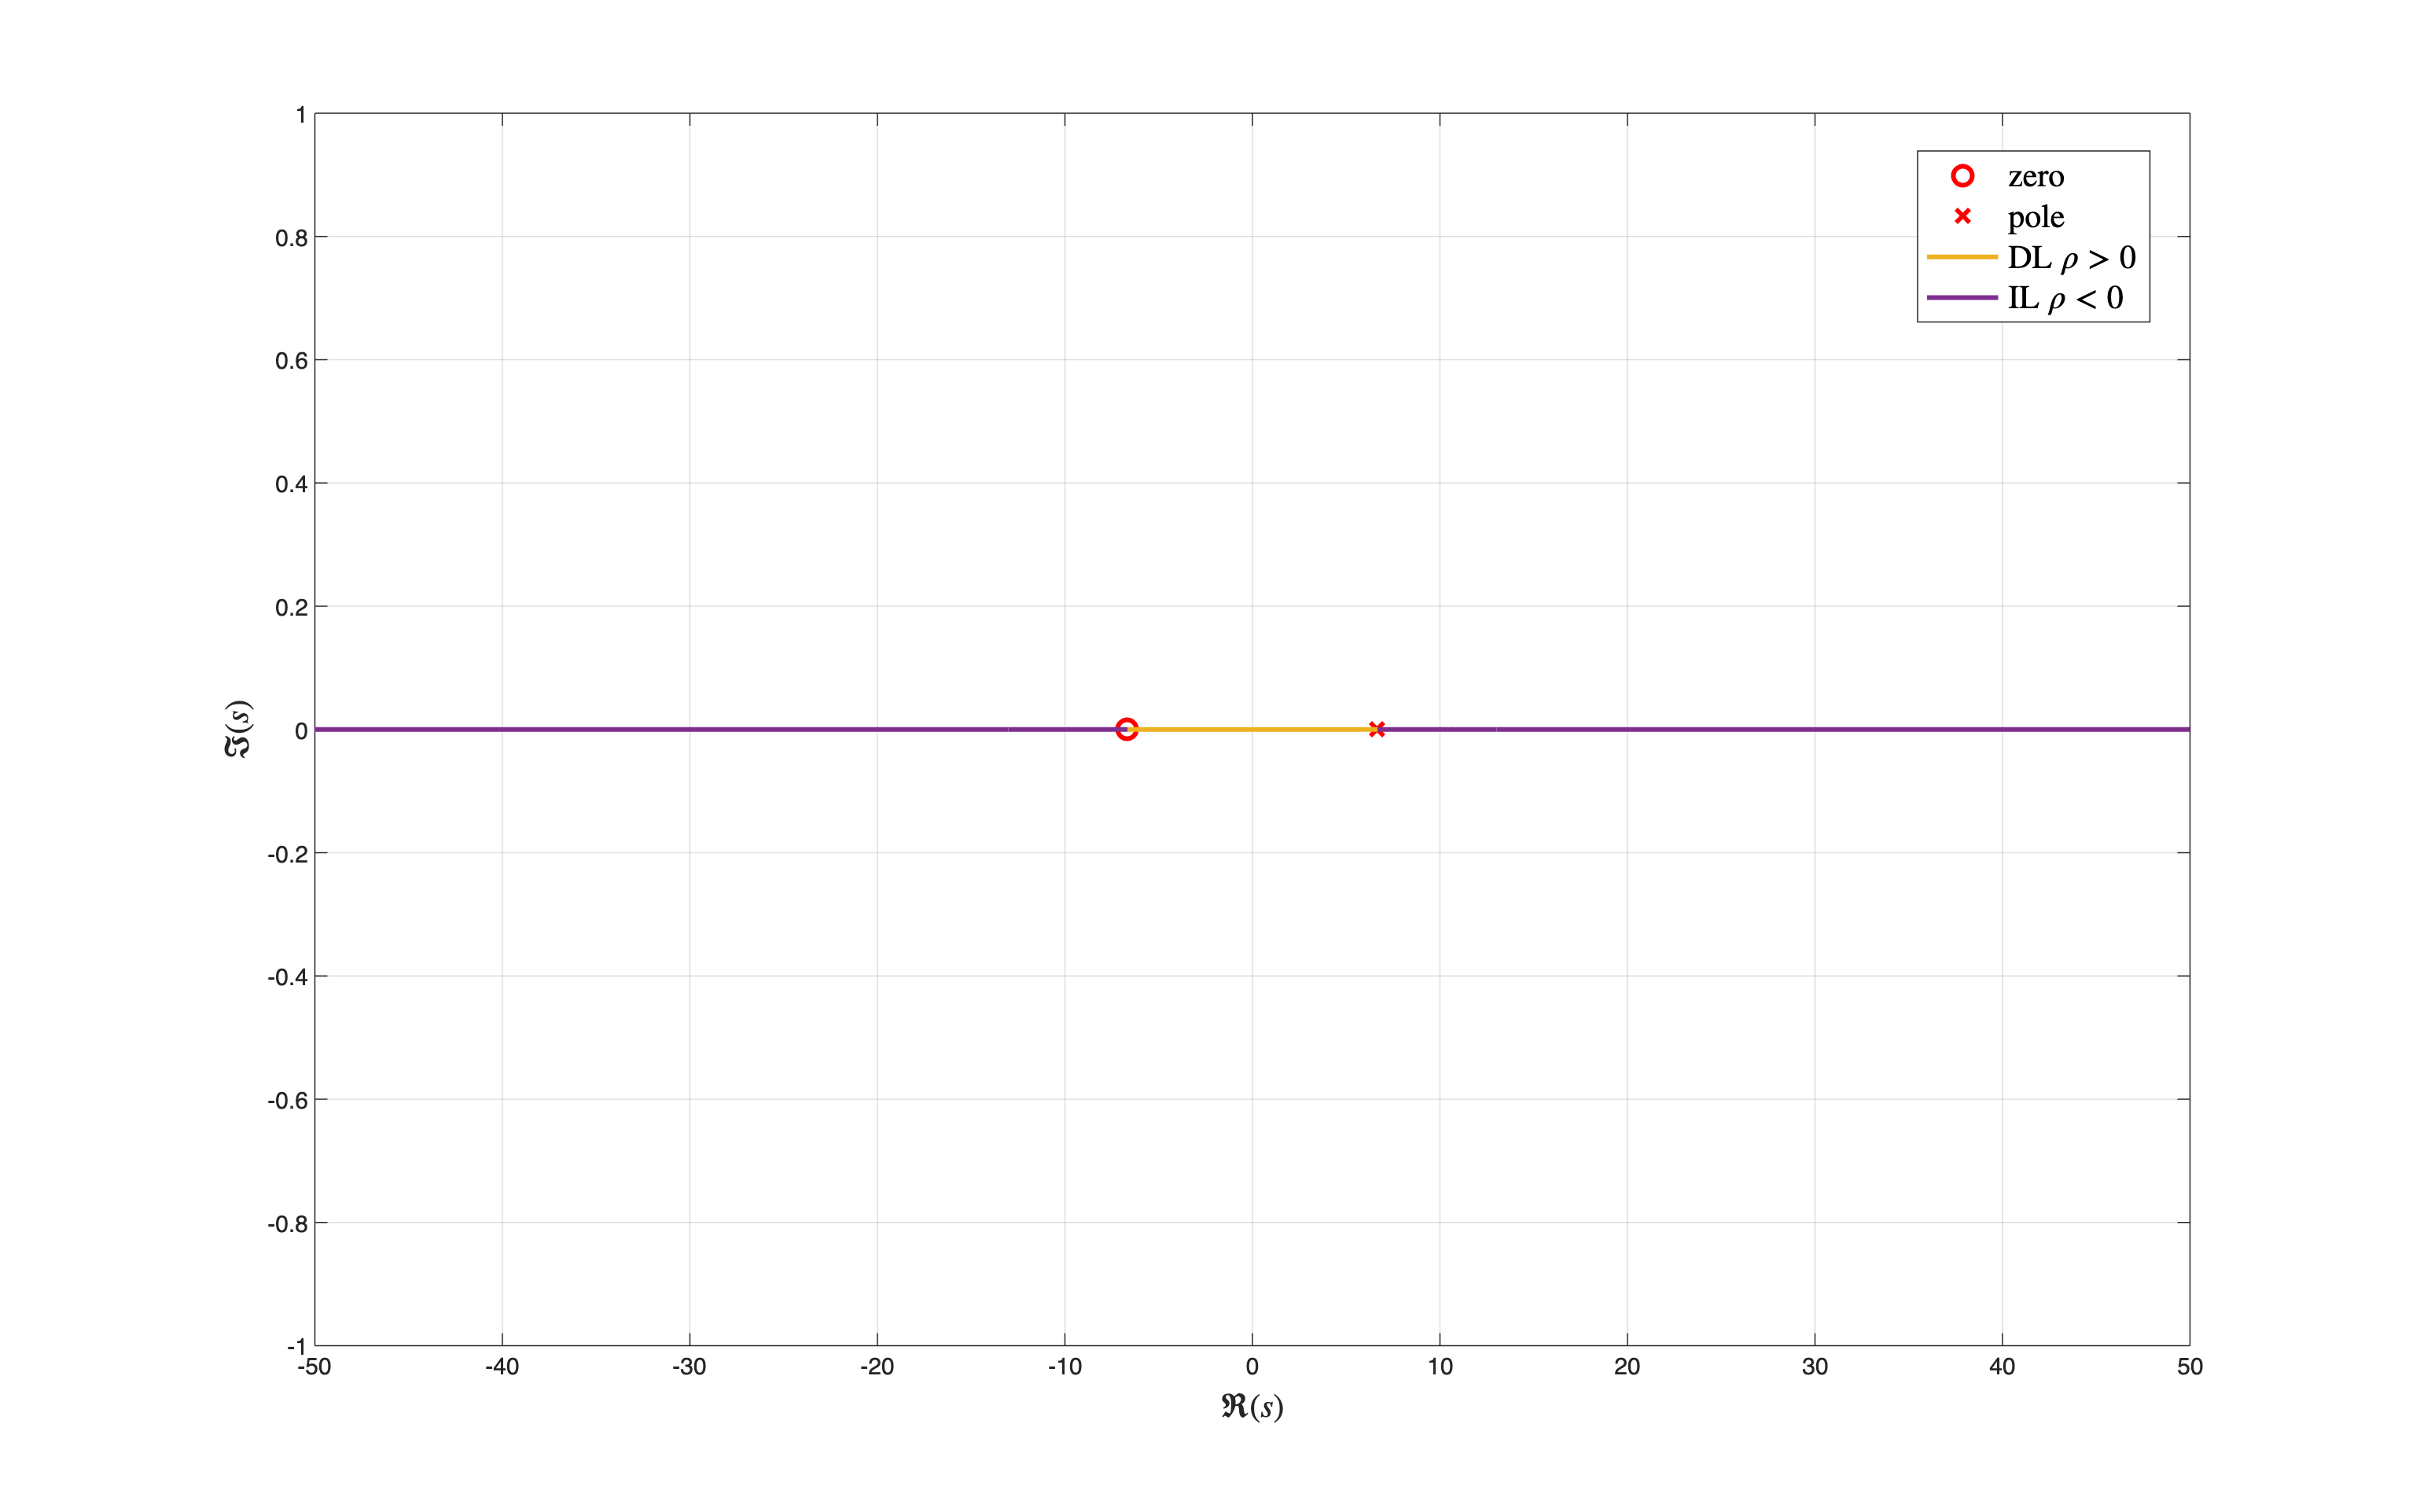


% plot both the loci in the same figure
figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.8]);

% let's start with zeros & poles 
h_s1 = plot(real(zL1),imag(zL1),'ro', ...
    real(pL1),imag(pL1),'rx', ...
    'MarkerSize',8, 'LineWidth',2); hold on;
hold on; grid on;
% the Direct Locus
h_rld1 = plot(real(r_DL), imag(r_DL), 'LineWidth', 2);
% the Inverse Locus
h_rid1 = plot(real(r_IL), imag(r_IL), 'LineWidth', 2);
xlabel('$\Re(s)$', 'Interpreter','latex', 'FontSize',14);
ylabel('$\Im(s)$', 'Interpreter','latex', 'FontSize',14);
legend([h_s1;h_rld1; h_rid1],'zero', 'pole', 'DL $\rho>0$', 'IL $\rho<0$', 'Interpreter', 'latex', 'Location', 'best', 'FontSize', 14)
xlim([-50, +50]); % focus on the zone near the origin

Let's verify that every value $\mu_2<0\,,\;\left\vert\mu_2 \right\vert>+\frac{5}{24}$ is feasible:

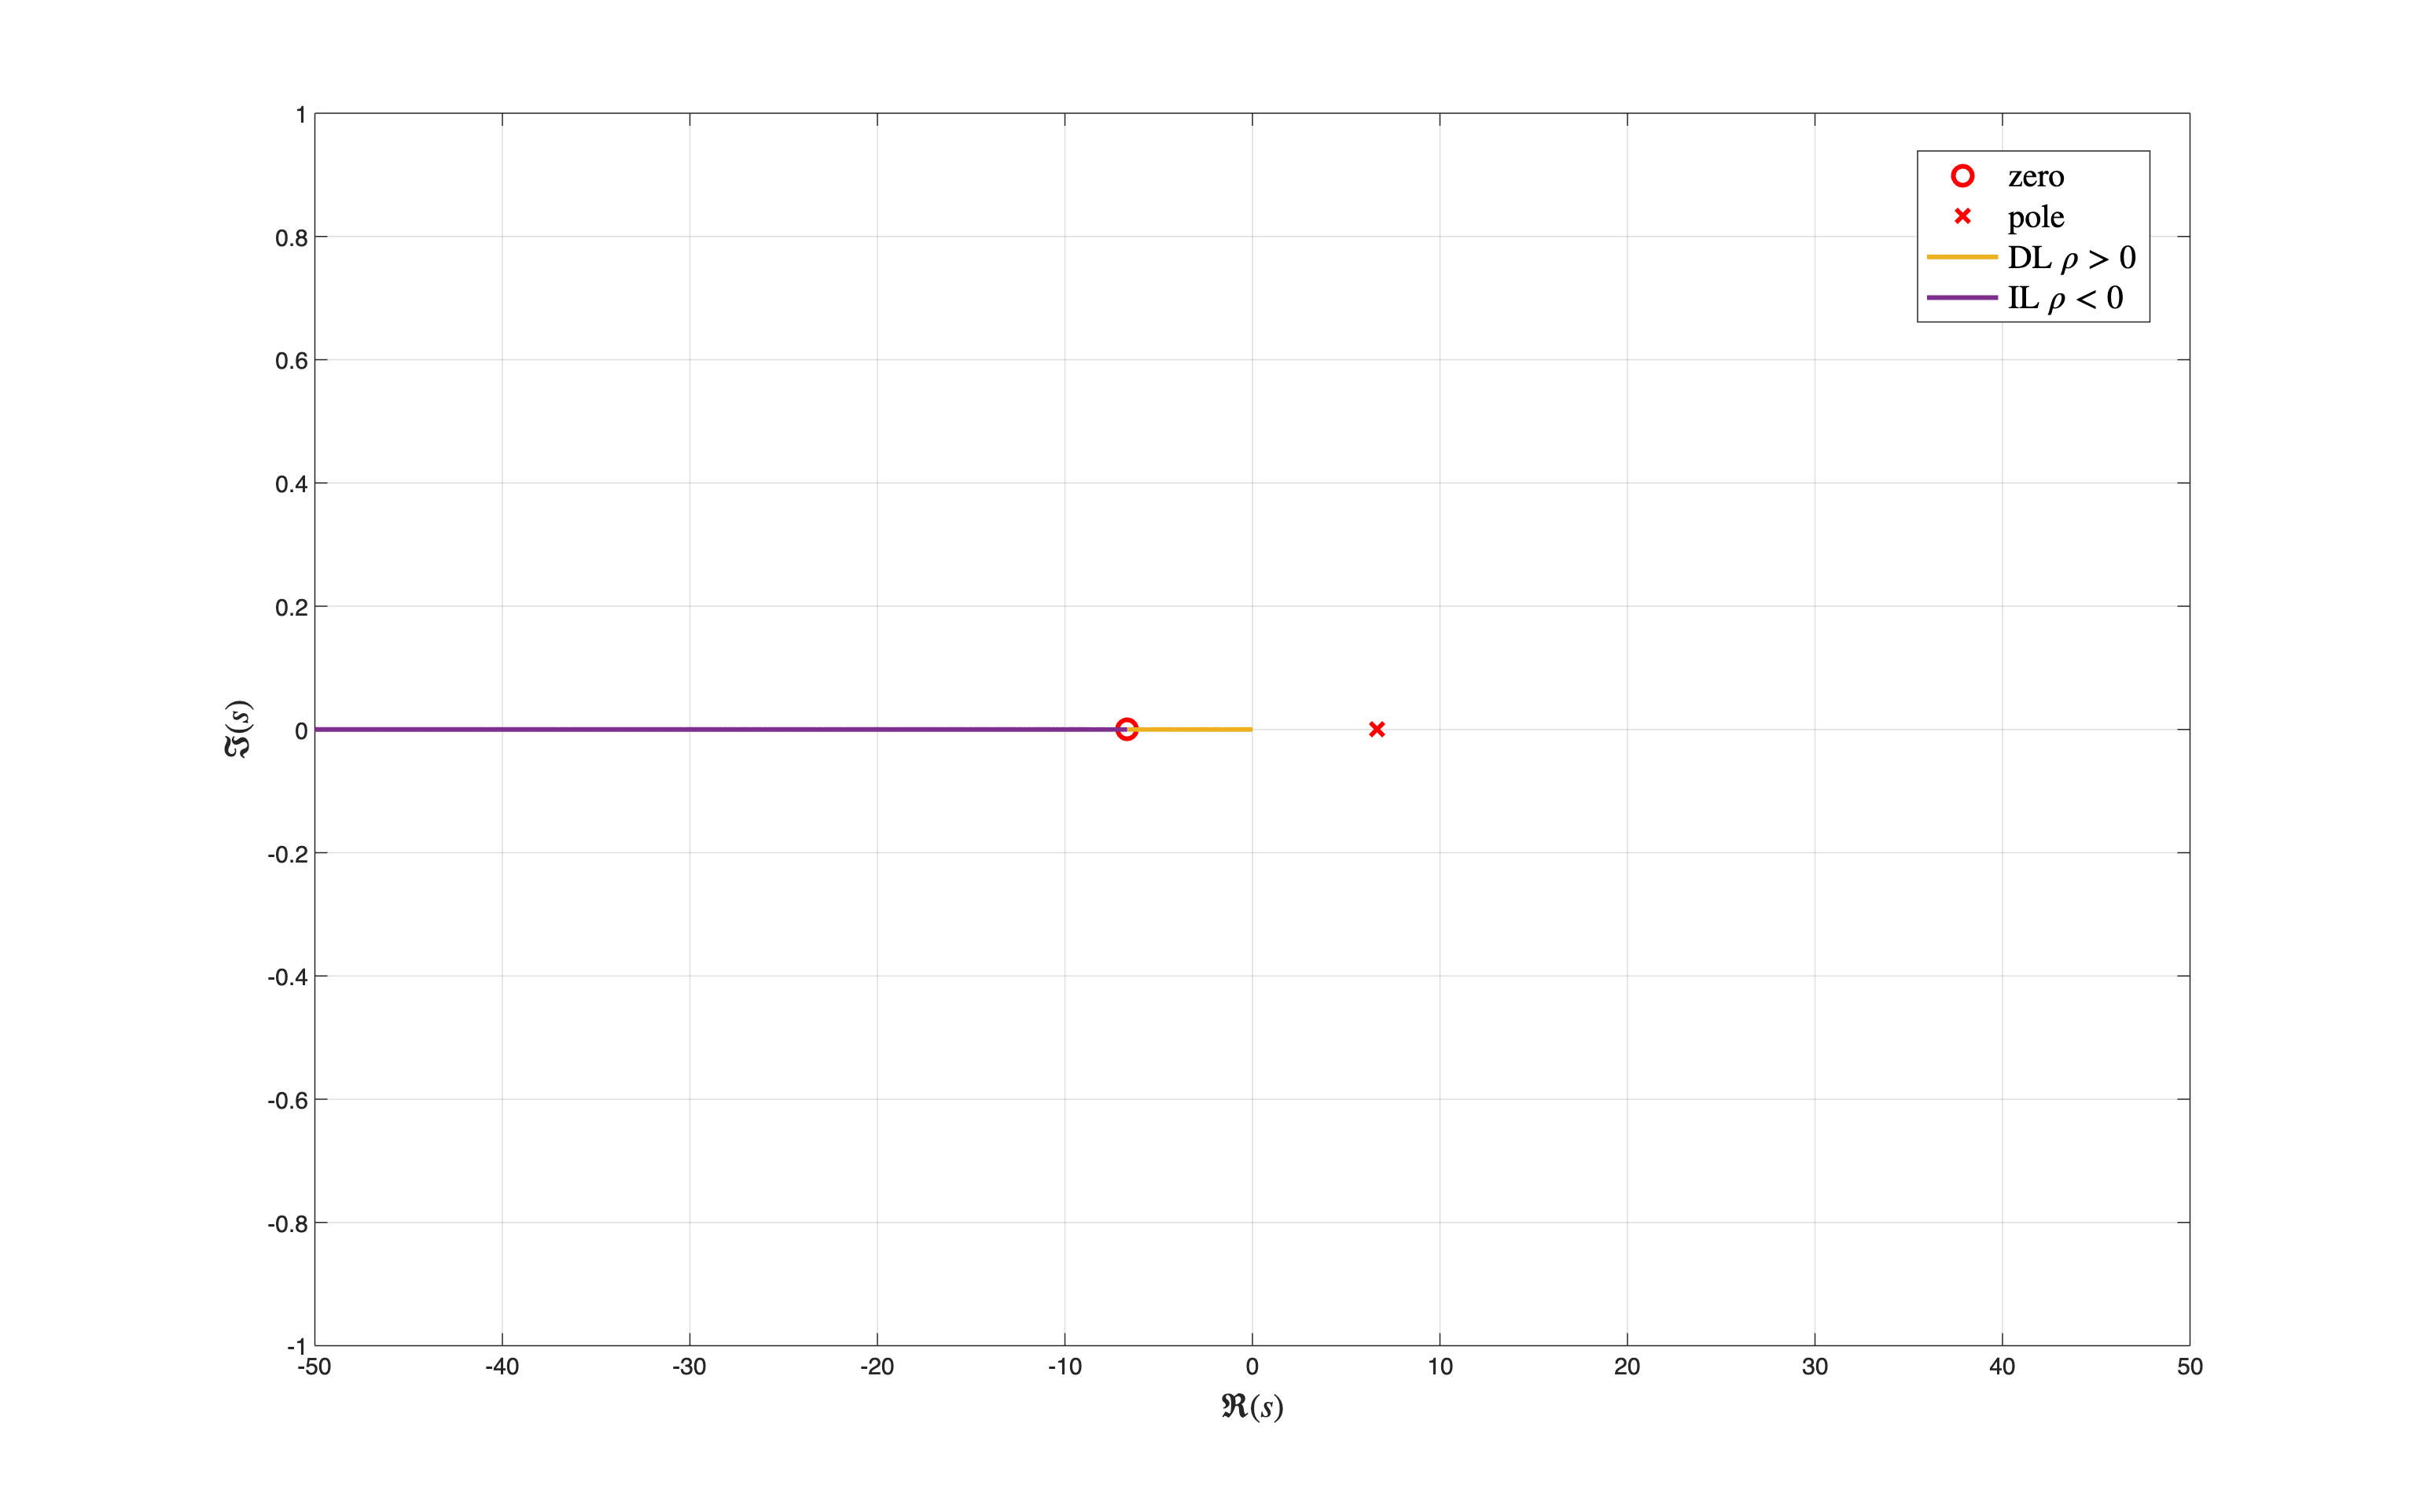

muSET = -logspace(log10(5/24+eps), log10(200), 1e3); % abs(mu2) greater than 5/24
rhoSET = -4.8*muSET;

[r_DL, rhoDL] = rlocus(L2_RL, rhoSET);  %  a set of points belonging to the DL
[r_IL, rhoIL] = rlocus(L2_RL, -rhoSET); %  a set of points belonging to the IL -- NOTE "-rhoSET"
% for details, refer to
% https://uk.mathworks.com/help/control/ref/dynamicsystem.rlocus.html
%
% NB an equivalent form is
% [r_IL, rhoIL] = rlocus(-L2_RL, rhoSET); % NOTE "-L2"

% plot both the loci in the same figure
figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.8]);

% let's start with zeros & poles 
h_s1 = plot(real(zL1),imag(zL1),'ro', ...
    real(pL1),imag(pL1),'rx', ...
    'MarkerSize',8, 'LineWidth',2); hold on;
hold on; grid on;
% the Direct Locus
h_rld1 = plot(real(r_DL), imag(r_DL), 'LineWidth', 2);

% the Inverse Locus
h_rid1 = plot(real(r_IL), imag(r_IL), 'LineWidth', 2);
xlabel('$\Re(s)$', 'Interpreter','latex', 'FontSize',14);
ylabel('$\Im(s)$', 'Interpreter','latex', 'FontSize',14);
legend([h_s1;h_rld1; h_rid1],'zero', 'pole', 'DL $\rho>0$', 'IL $\rho<0$', 'Interpreter', 'latex', 'Location', 'best', 'FontSize', 14)
xlim([-50, +50]); % focus on the zone near the origin

Indeed, we obtained always a pole with negative real part, so every value for the gain constant $\mu_2$ such that  $\mu_2<0\,,\;\left\vert\mu_2 \right\vert>+\frac{5}{24}$ is feasible!

Let's choose $\mu_2=-0.38685$, in order to place the pole of $F_2(s)$ on the left side with respect to the open-loop zero. **Hint**: you can proficiently use the MATLAB command `rlocfind` in order to select efficiently the gain $\mu_2$ (indeed, the "magic number" $\mu_2=-0.38685$ -- and the corresponding value of $\rho$ -- allows to have the closed-loop pole at $p=-2$).

mu2 = -0.38685;
rho = -4.8*mu2;
F2s_1stTrial = feedback(rho*L2_RL,1, -1)


F2s_1stTrial =
 
  1.857 s + 12.38
  ---------------
  2.857 s + 5.713
 
Continuous-time transfer function.
Model Properties



zpk(F2s_1stTrial)


ans =
 
  0.64997 (s+6.667)
  -----------------
        (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


### Design of the Outer Loop Controller

Let's compute the closed-loop transfer function of the inner loop

% let's define the transfer function builder element
% s=tf('s');
% 
% Gs = (1+2*s)/((1-s)*(1+10*s)); % the unstable process G(s)

C2s = tf(mu2) % the stabilising controller


C2s =
 
  -0.3869
 
Static gain.
Model Properties


% Note the sign vs. the transfer function L2_RL
zpk(Gs)


ans =
 
  -4.8 (s+6.667)
  --------------
    (s-6.667)
 
Continuous-time zero/pole/gain model.
Model Properties


F2s = zpk(feedback(C2s*Gs, 1, -1))


F2s =
 
  0.64997 (s+6.667)
  -----------------
        (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


**Important** **Remark**: Design requirements do not concern static performance at all. This authorises us to choose a "type $g=0$" controller for $C_1(s)$.

Let's start by selecting simply $C_1(s) = \mu_1 = 1$.

#### **First** **Step**: 

Let us analyse the frequency response of the open-loop system $L_1(s)$:


$$L_1(s) = C_1(s) \, F_2(s) = \mu_1 \cdot 0.64997\,\frac{\left(s+\frac{20}{3}\right)}{\left(s+2\right)}$$


What characteristics does it have? Can the requirements be met with a simple controller? 

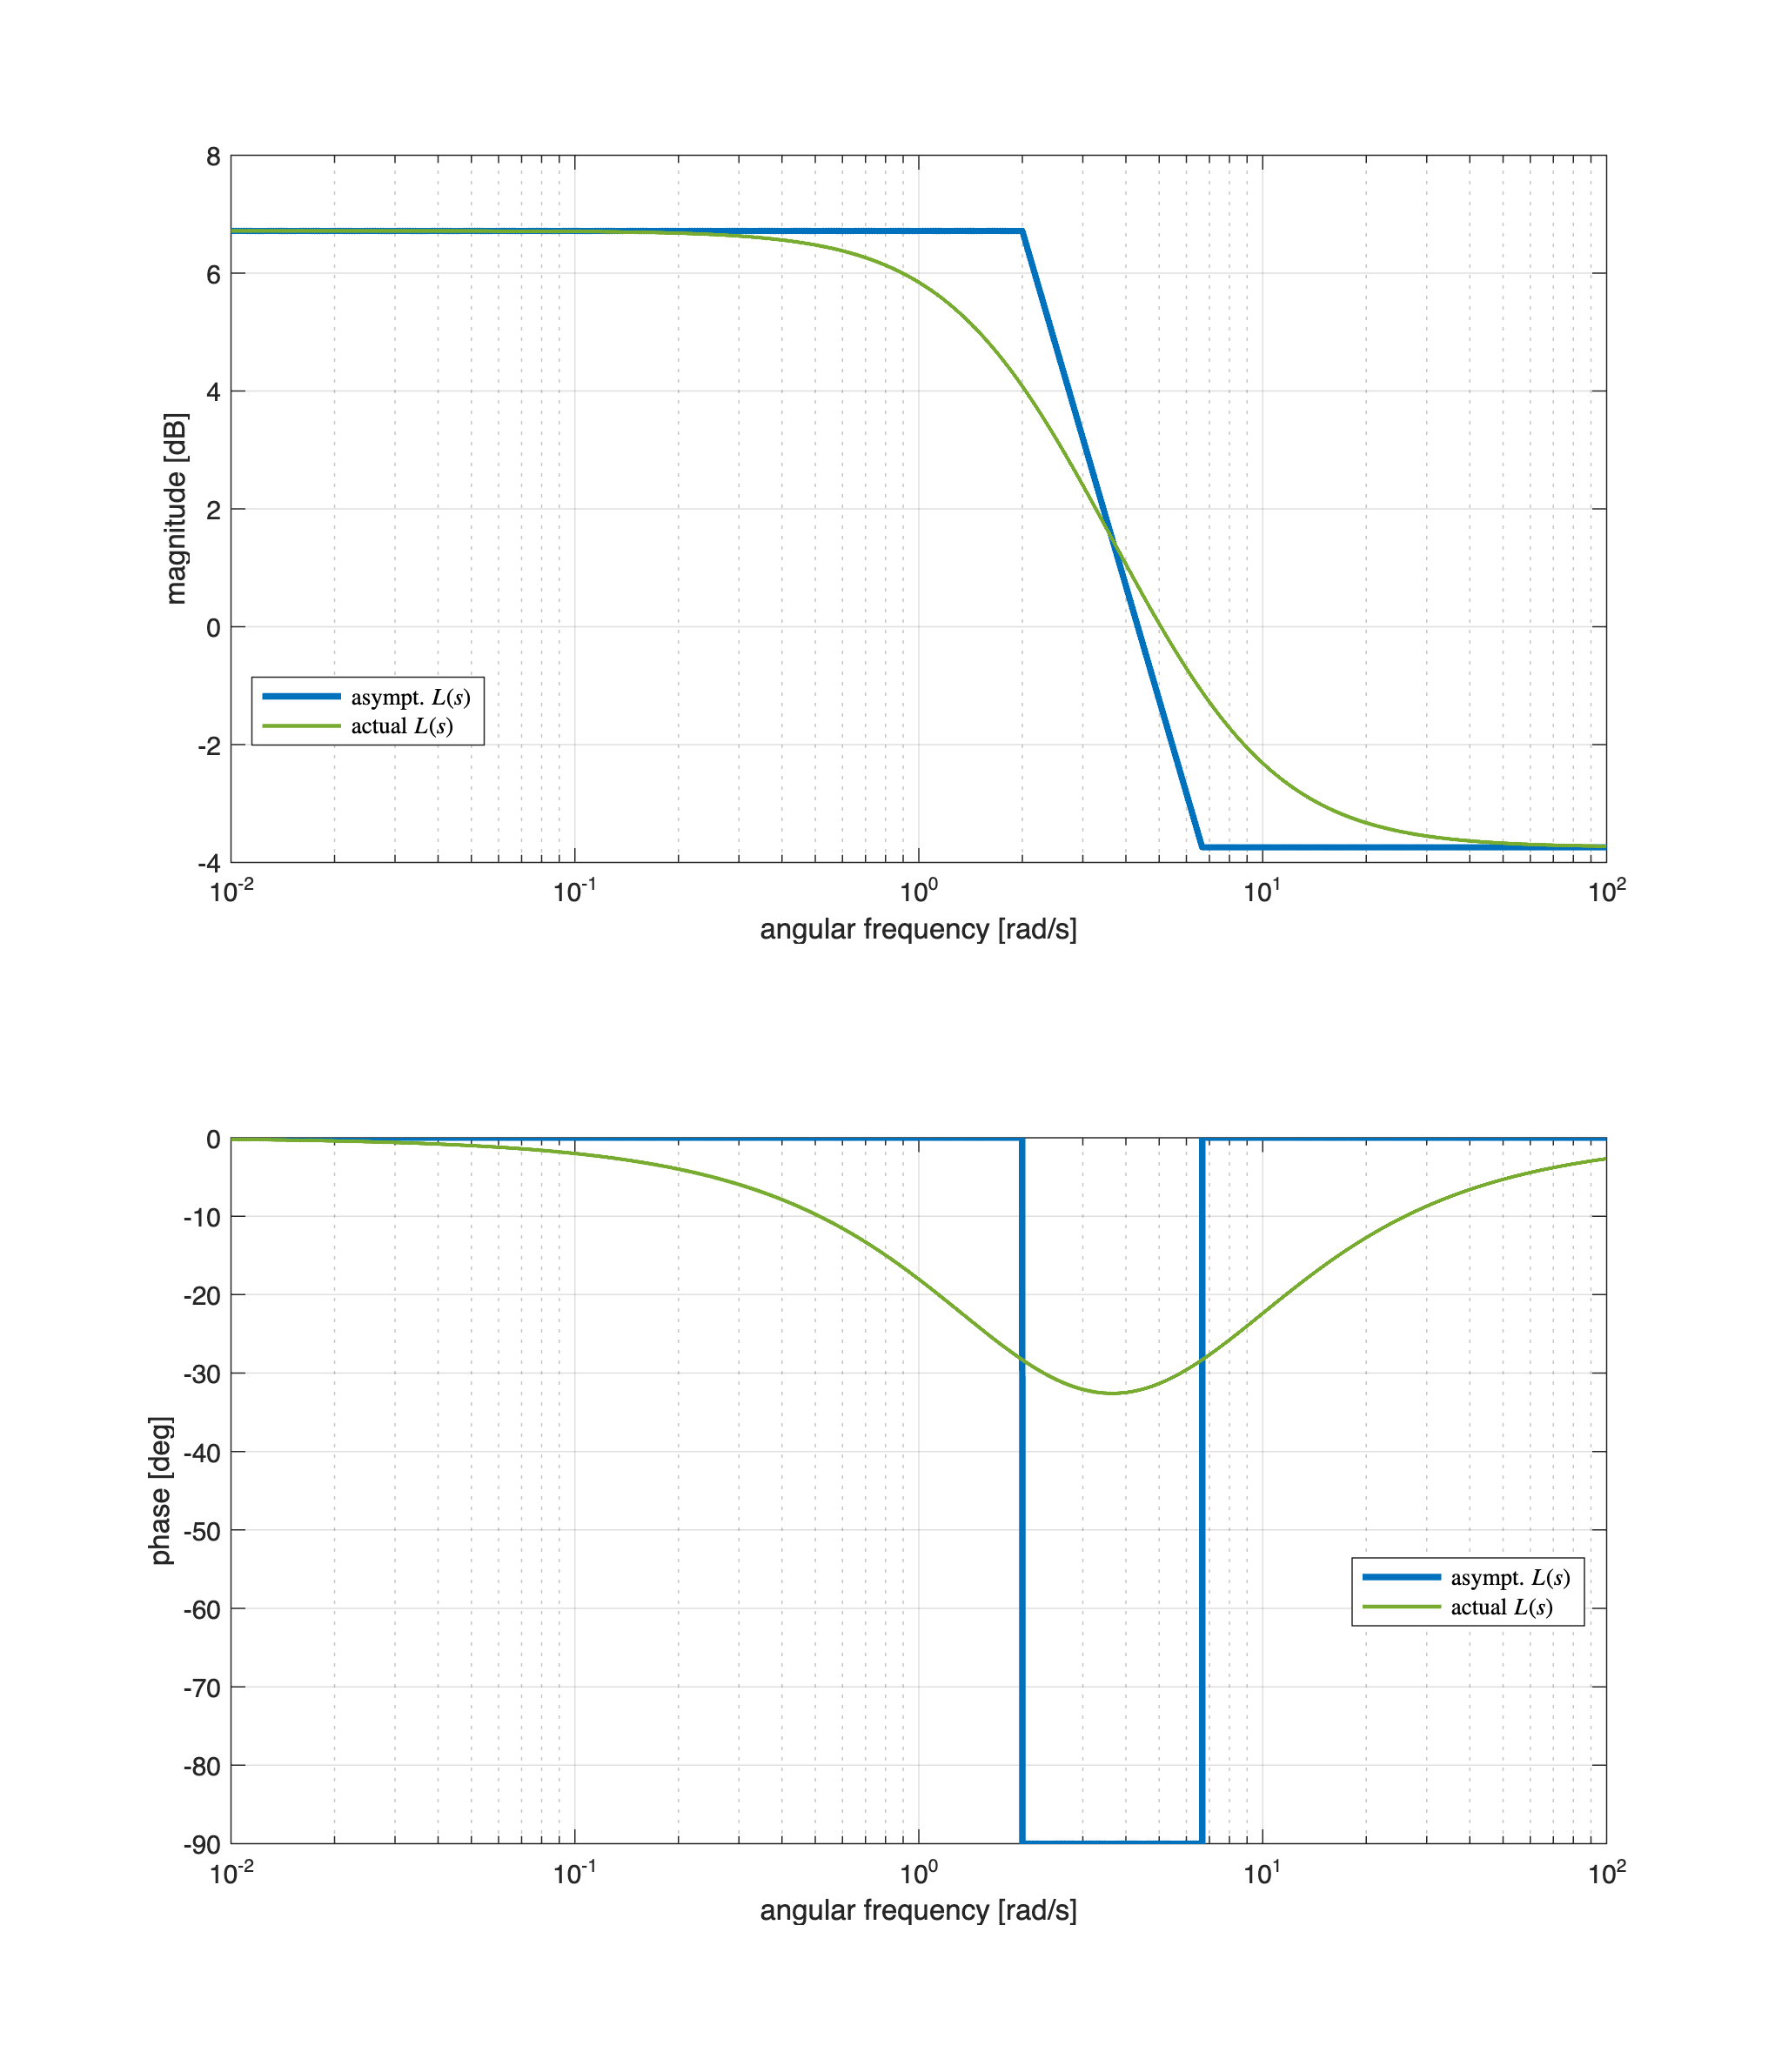

muC1 = 1;
C1s = muC1;

Cs = C1s;


Ls = Cs * F2s;

omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ls, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');

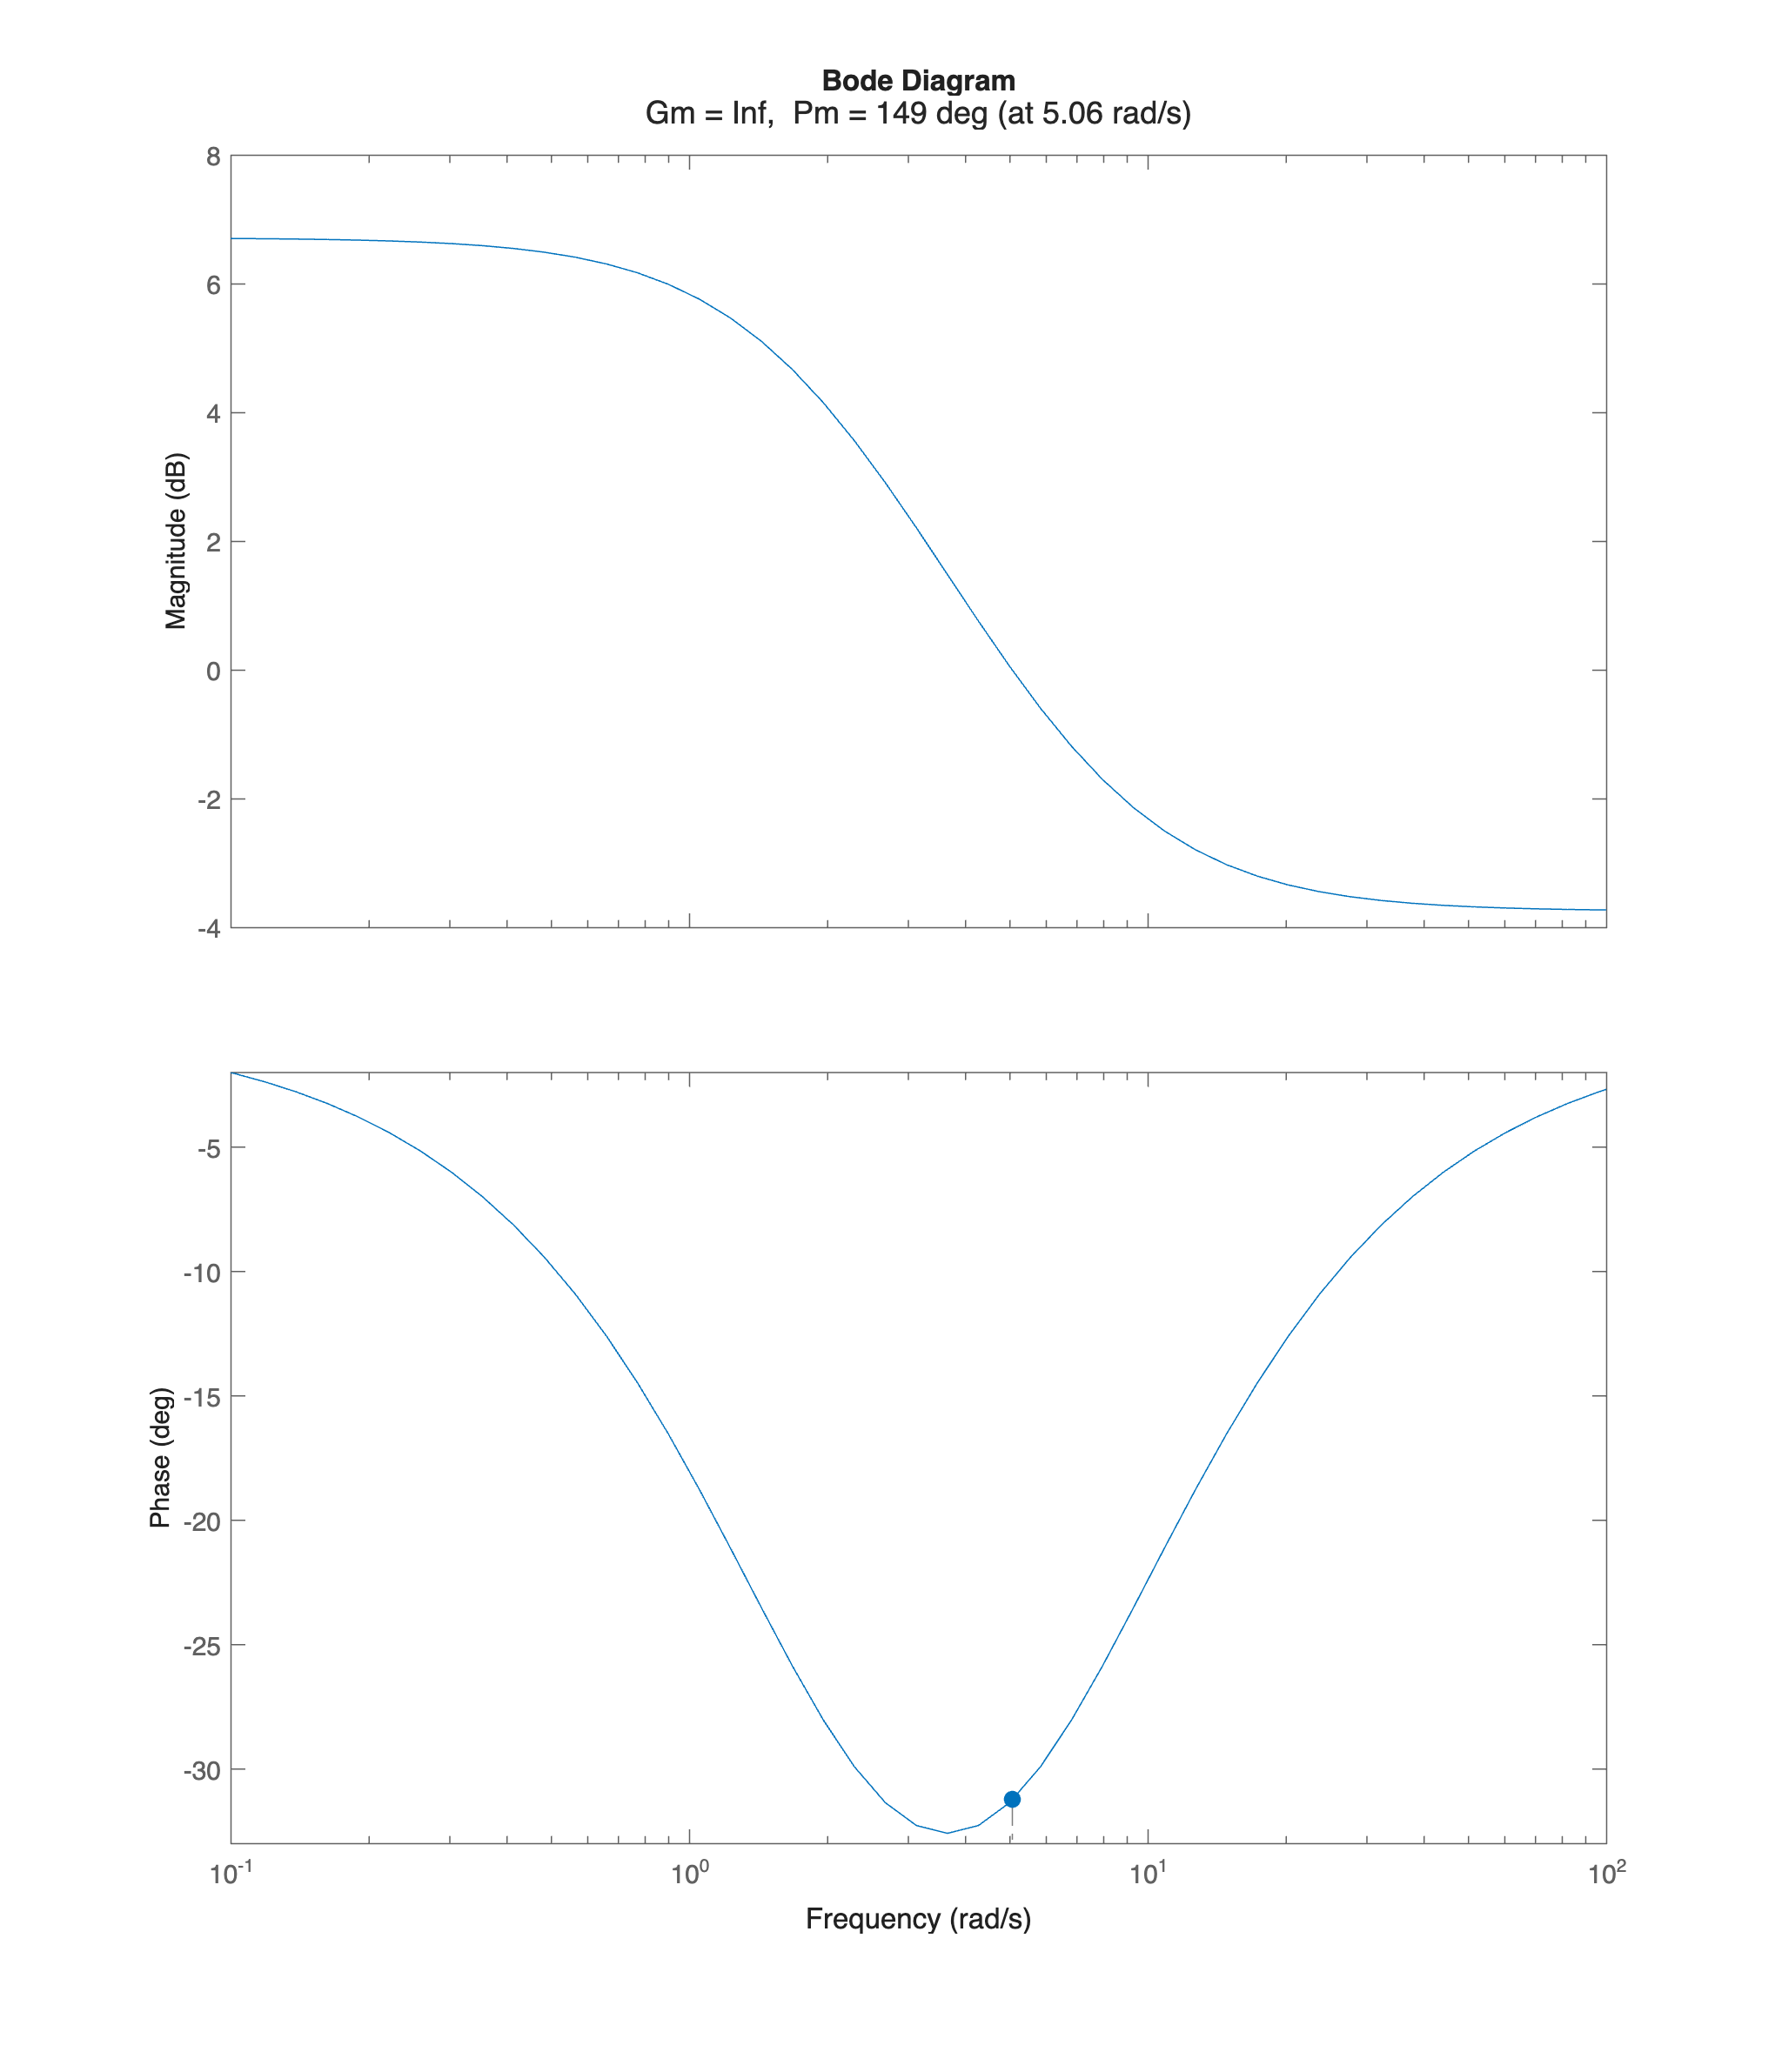

figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

margin(Ls)

#### Second **Step**: Cancelling Zero and Pole

The actual crossover frequency $\omega_c$ is too low. We can improve the system performance, by cancelling both the pole and the zero and inserting a new proper pole in order to fulfil the requirements.

muC1 = 1;
pF2 = pole(F2s)

pF2 = -1.9996

C1s = muC1 * (s-pF2)/((s+20/3)*(s+20));

Ls =minreal(C1s * F2s)


Ls =
 
  0.64997
  -------
  (s+20)
 
Continuous-time zero/pole/gain model.
Model Properties


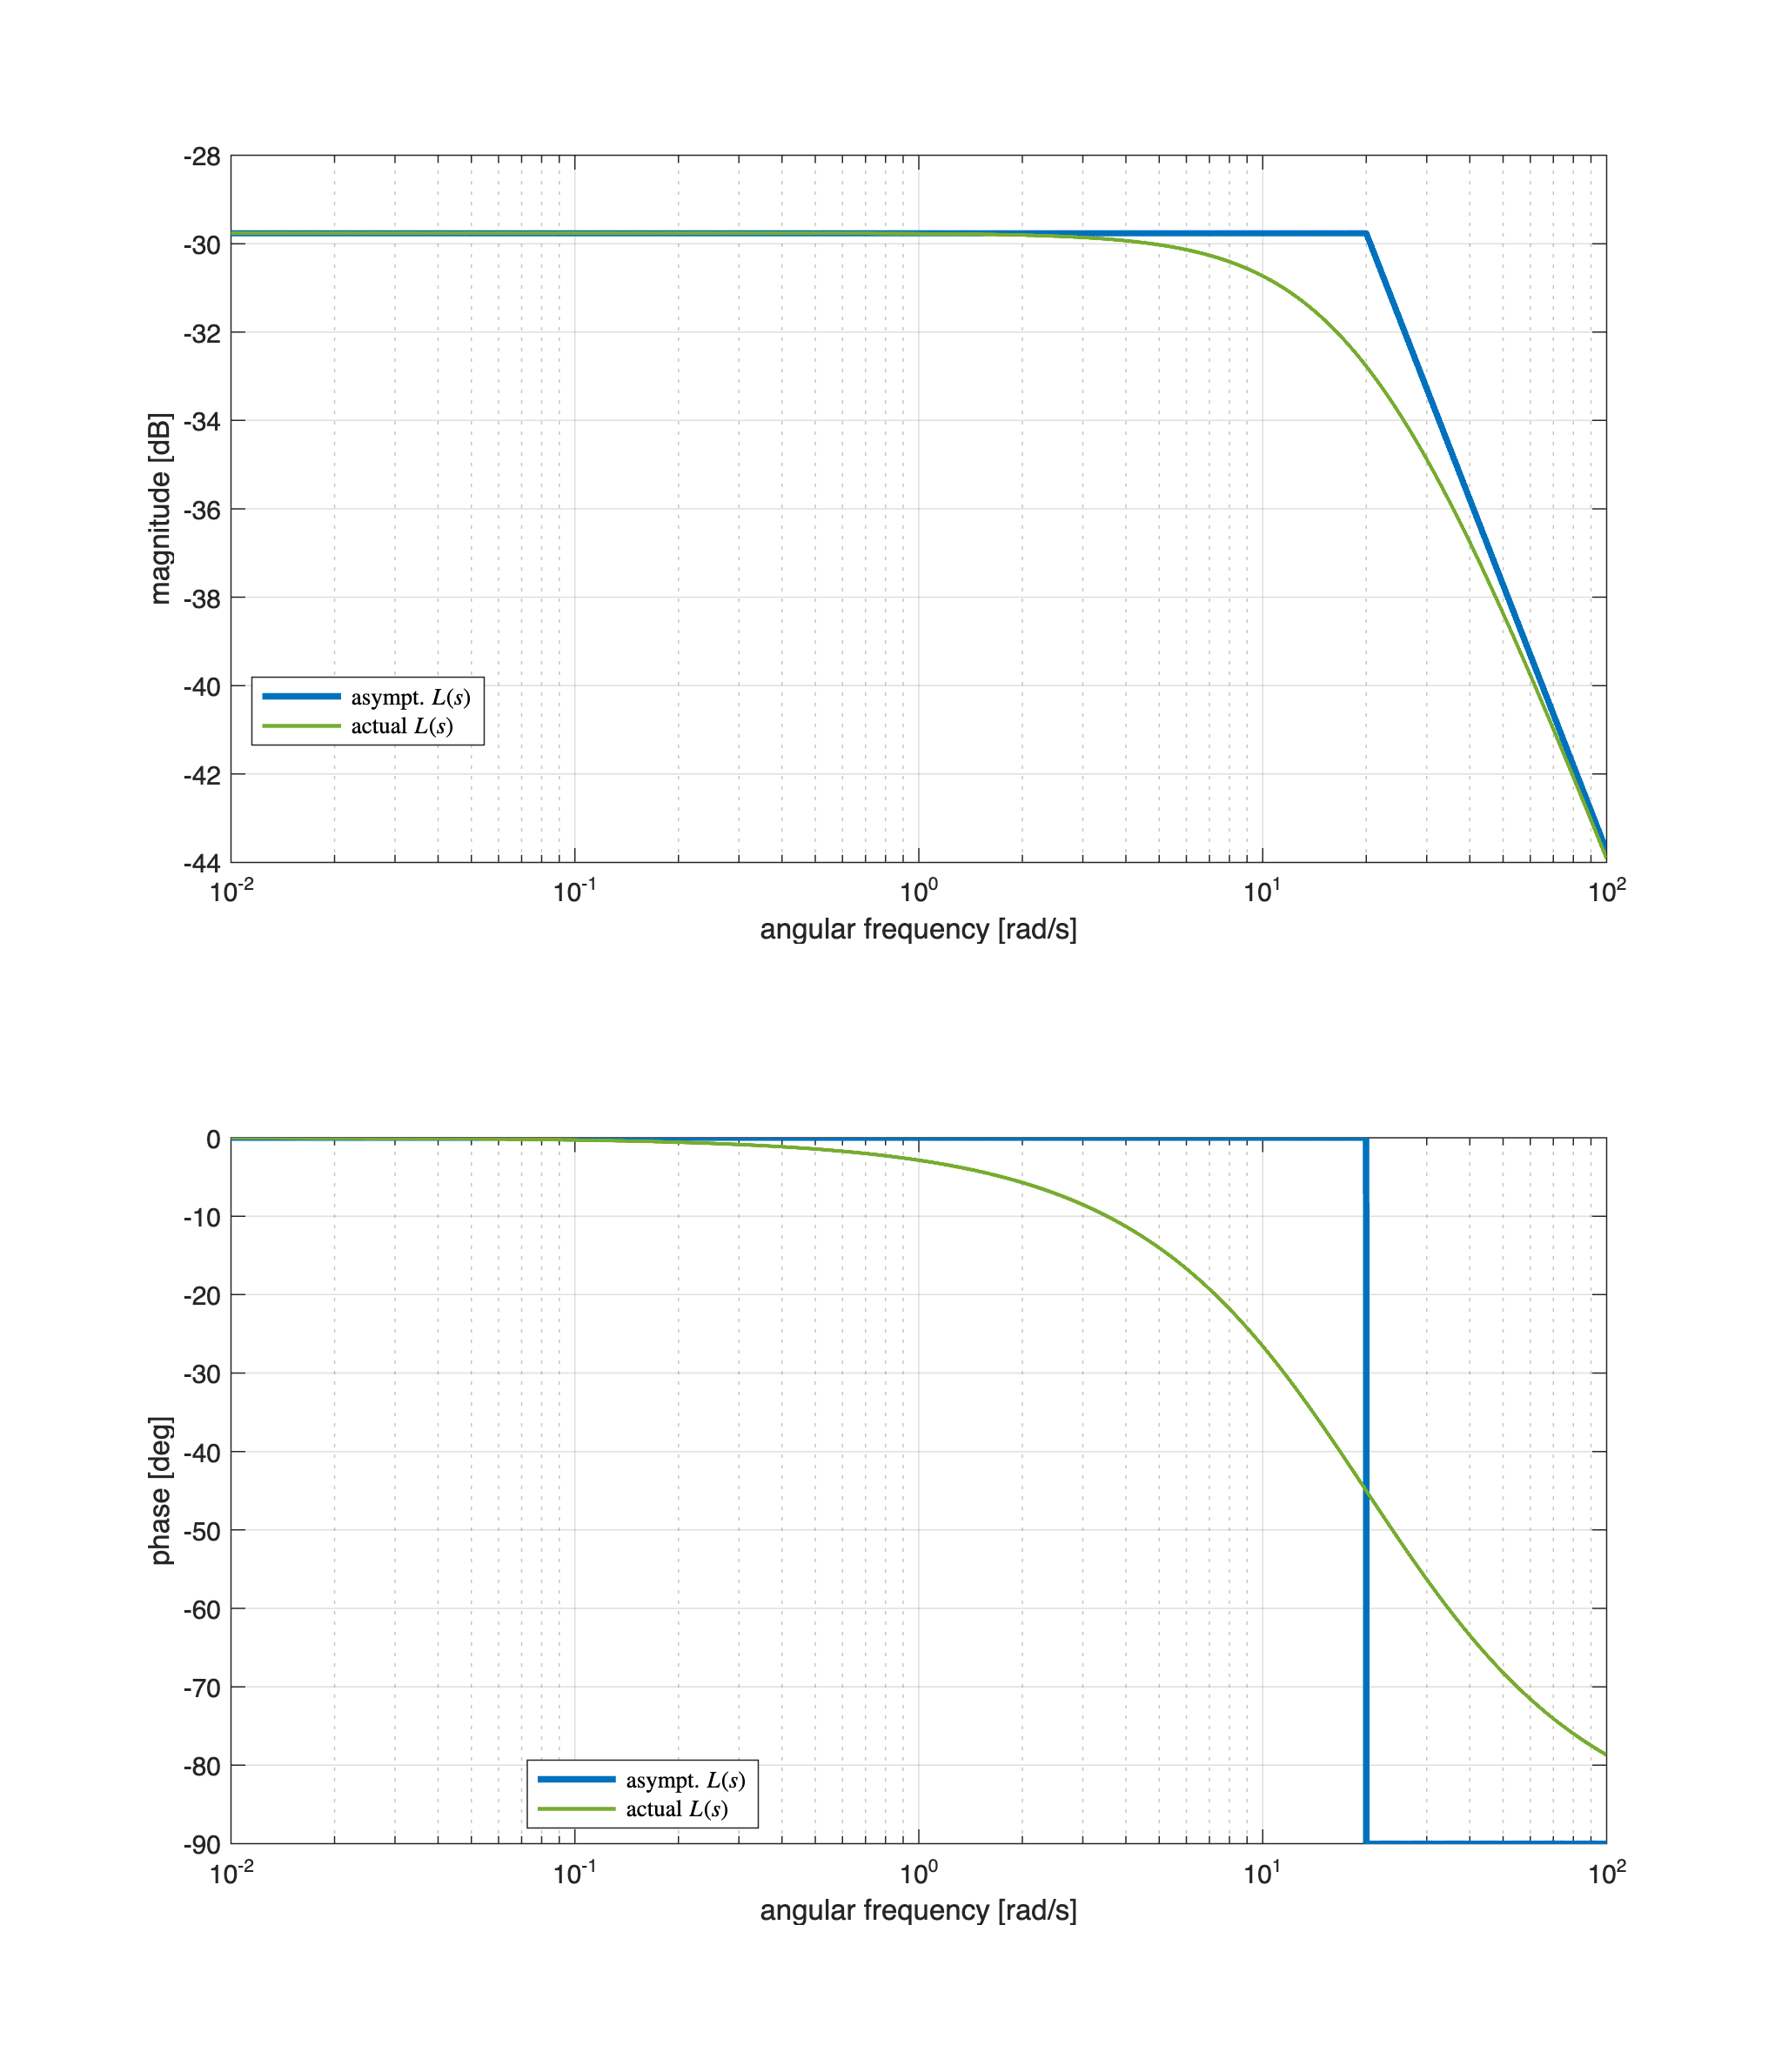


omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )


hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ls, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');

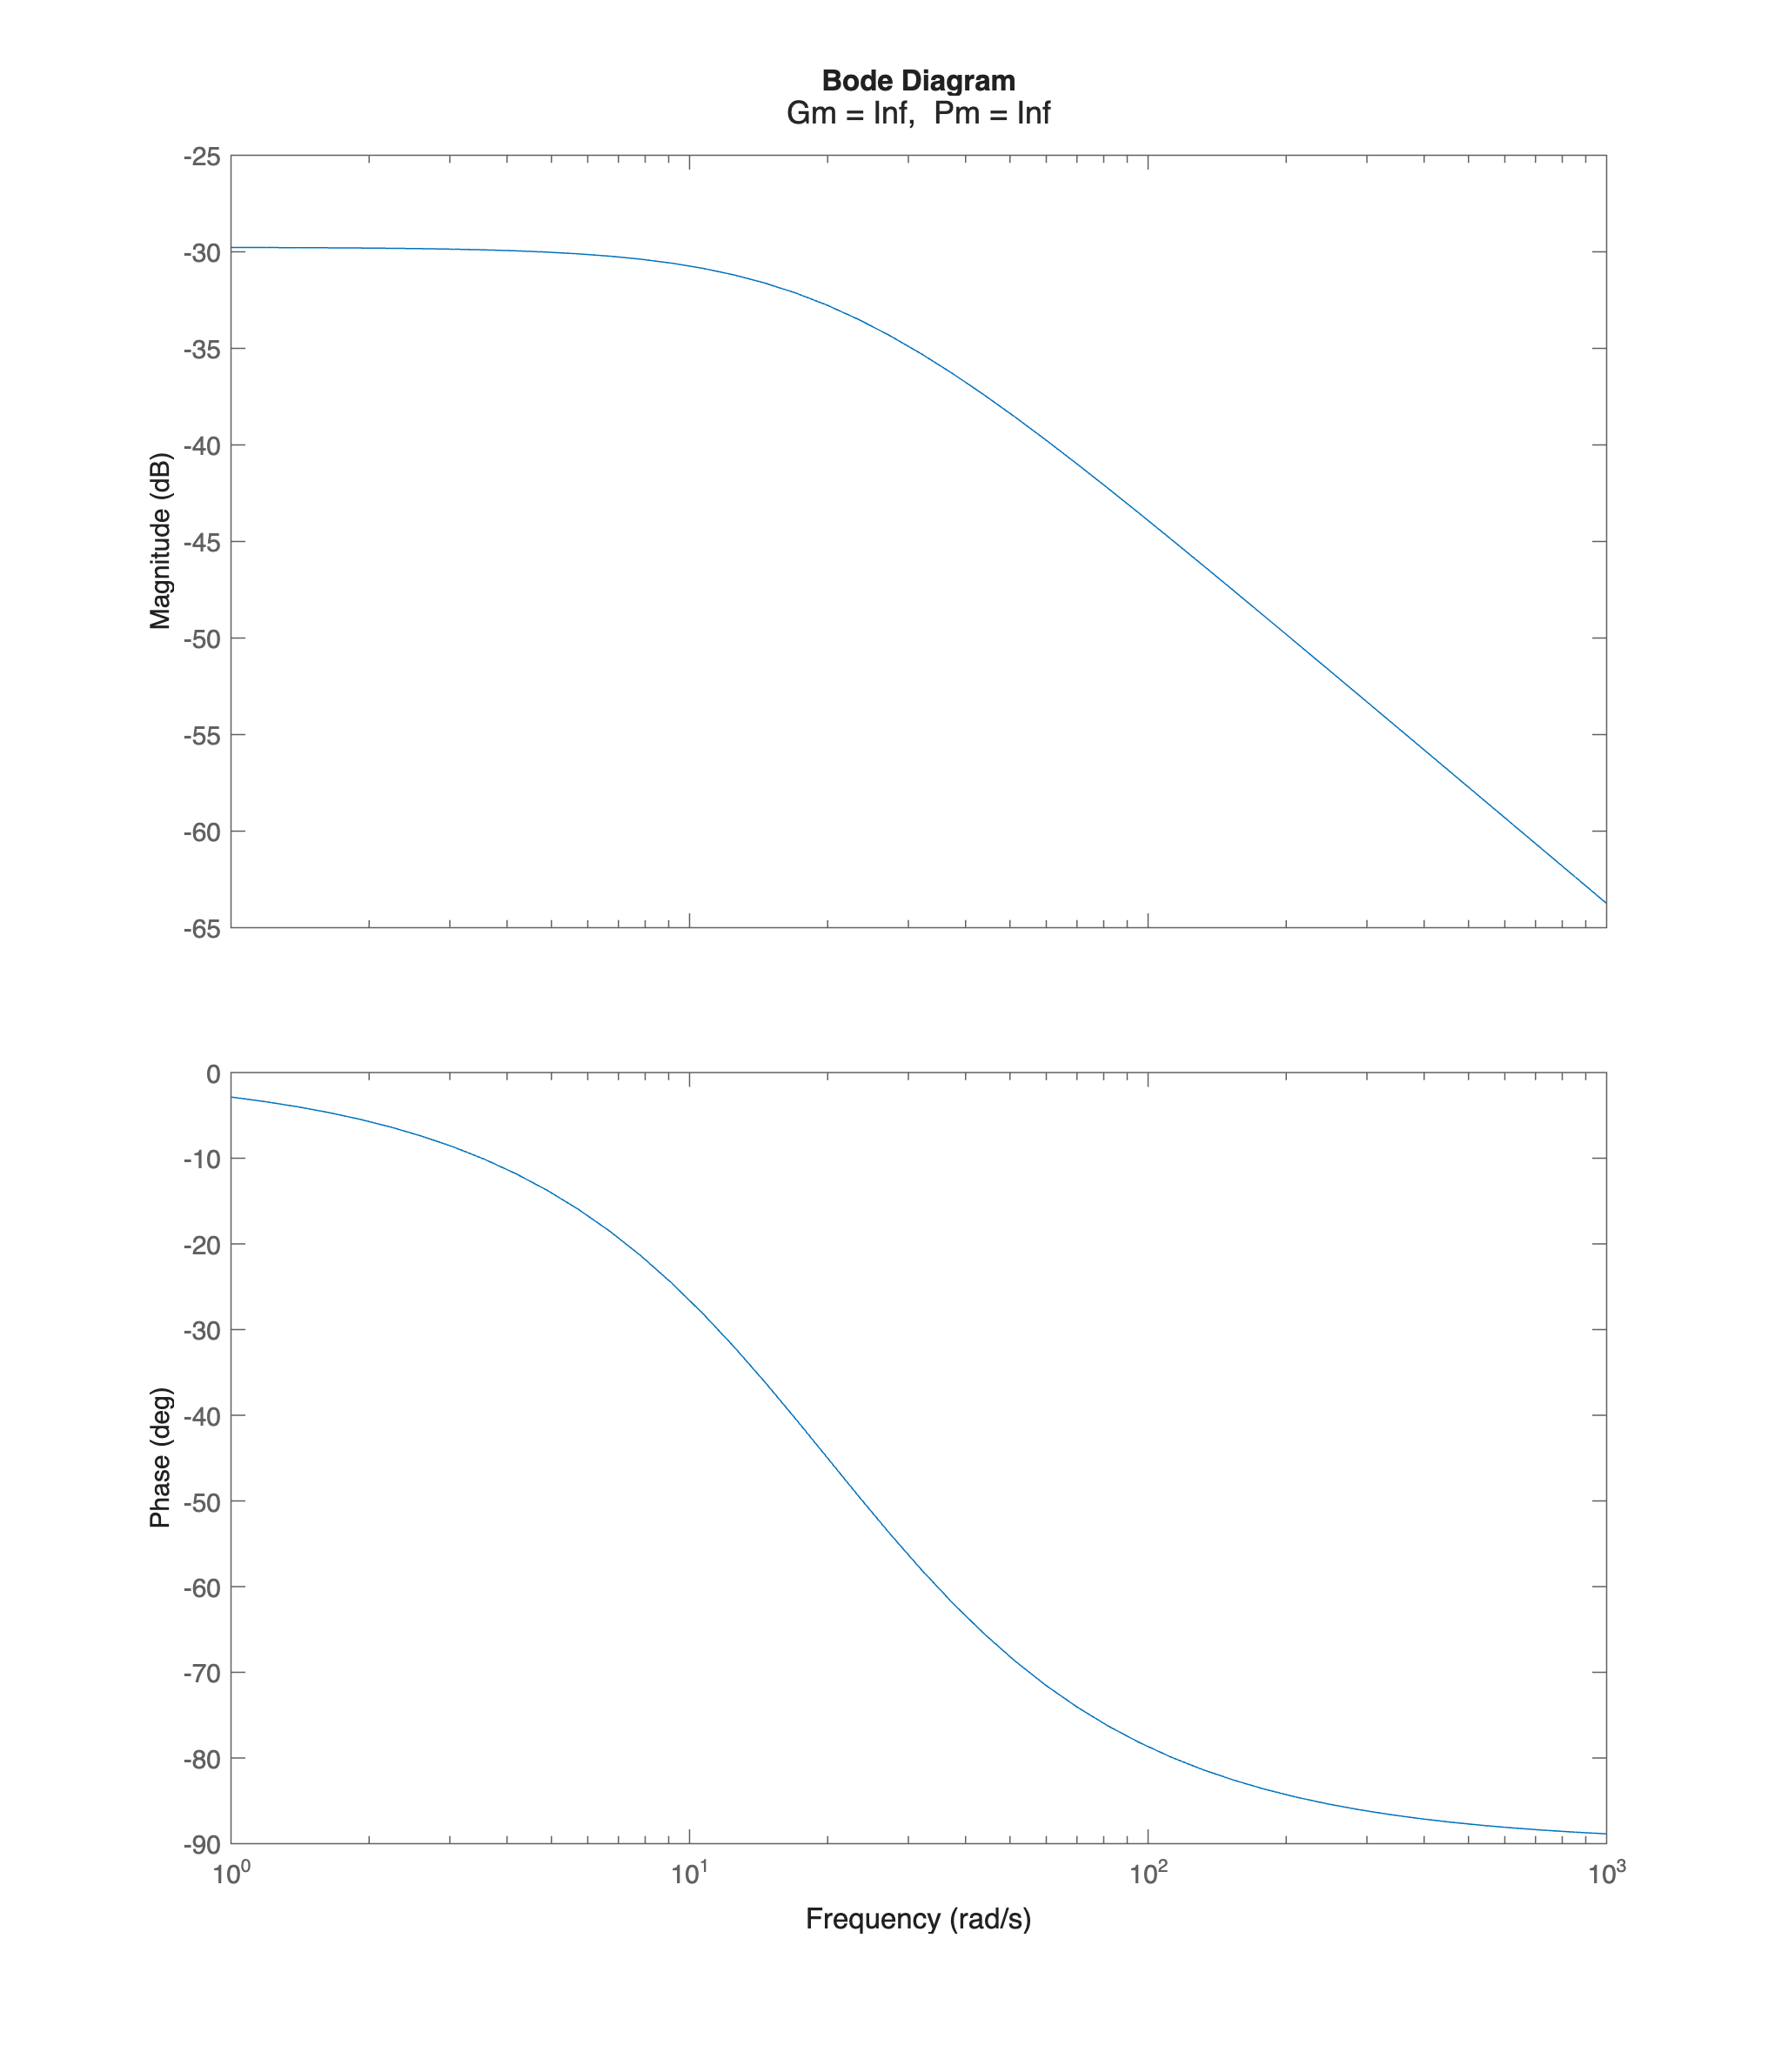

figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

margin(Ls)

Now we have simply to tune the static gain of the outer controller $C_1(s)$:

M20 = abs(freqresp(Ls, 20)); 
% the magnitude of the frequency response at the ang. frequency 20 rad/s

muC1new = 1/M20;
C1snew = muC1new * C1s;

Ls_new =minreal(C1snew * F2s)


Ls_new =
 
  28.284
  ------
  (s+20)
 
Continuous-time zero/pole/gain model.
Model Properties


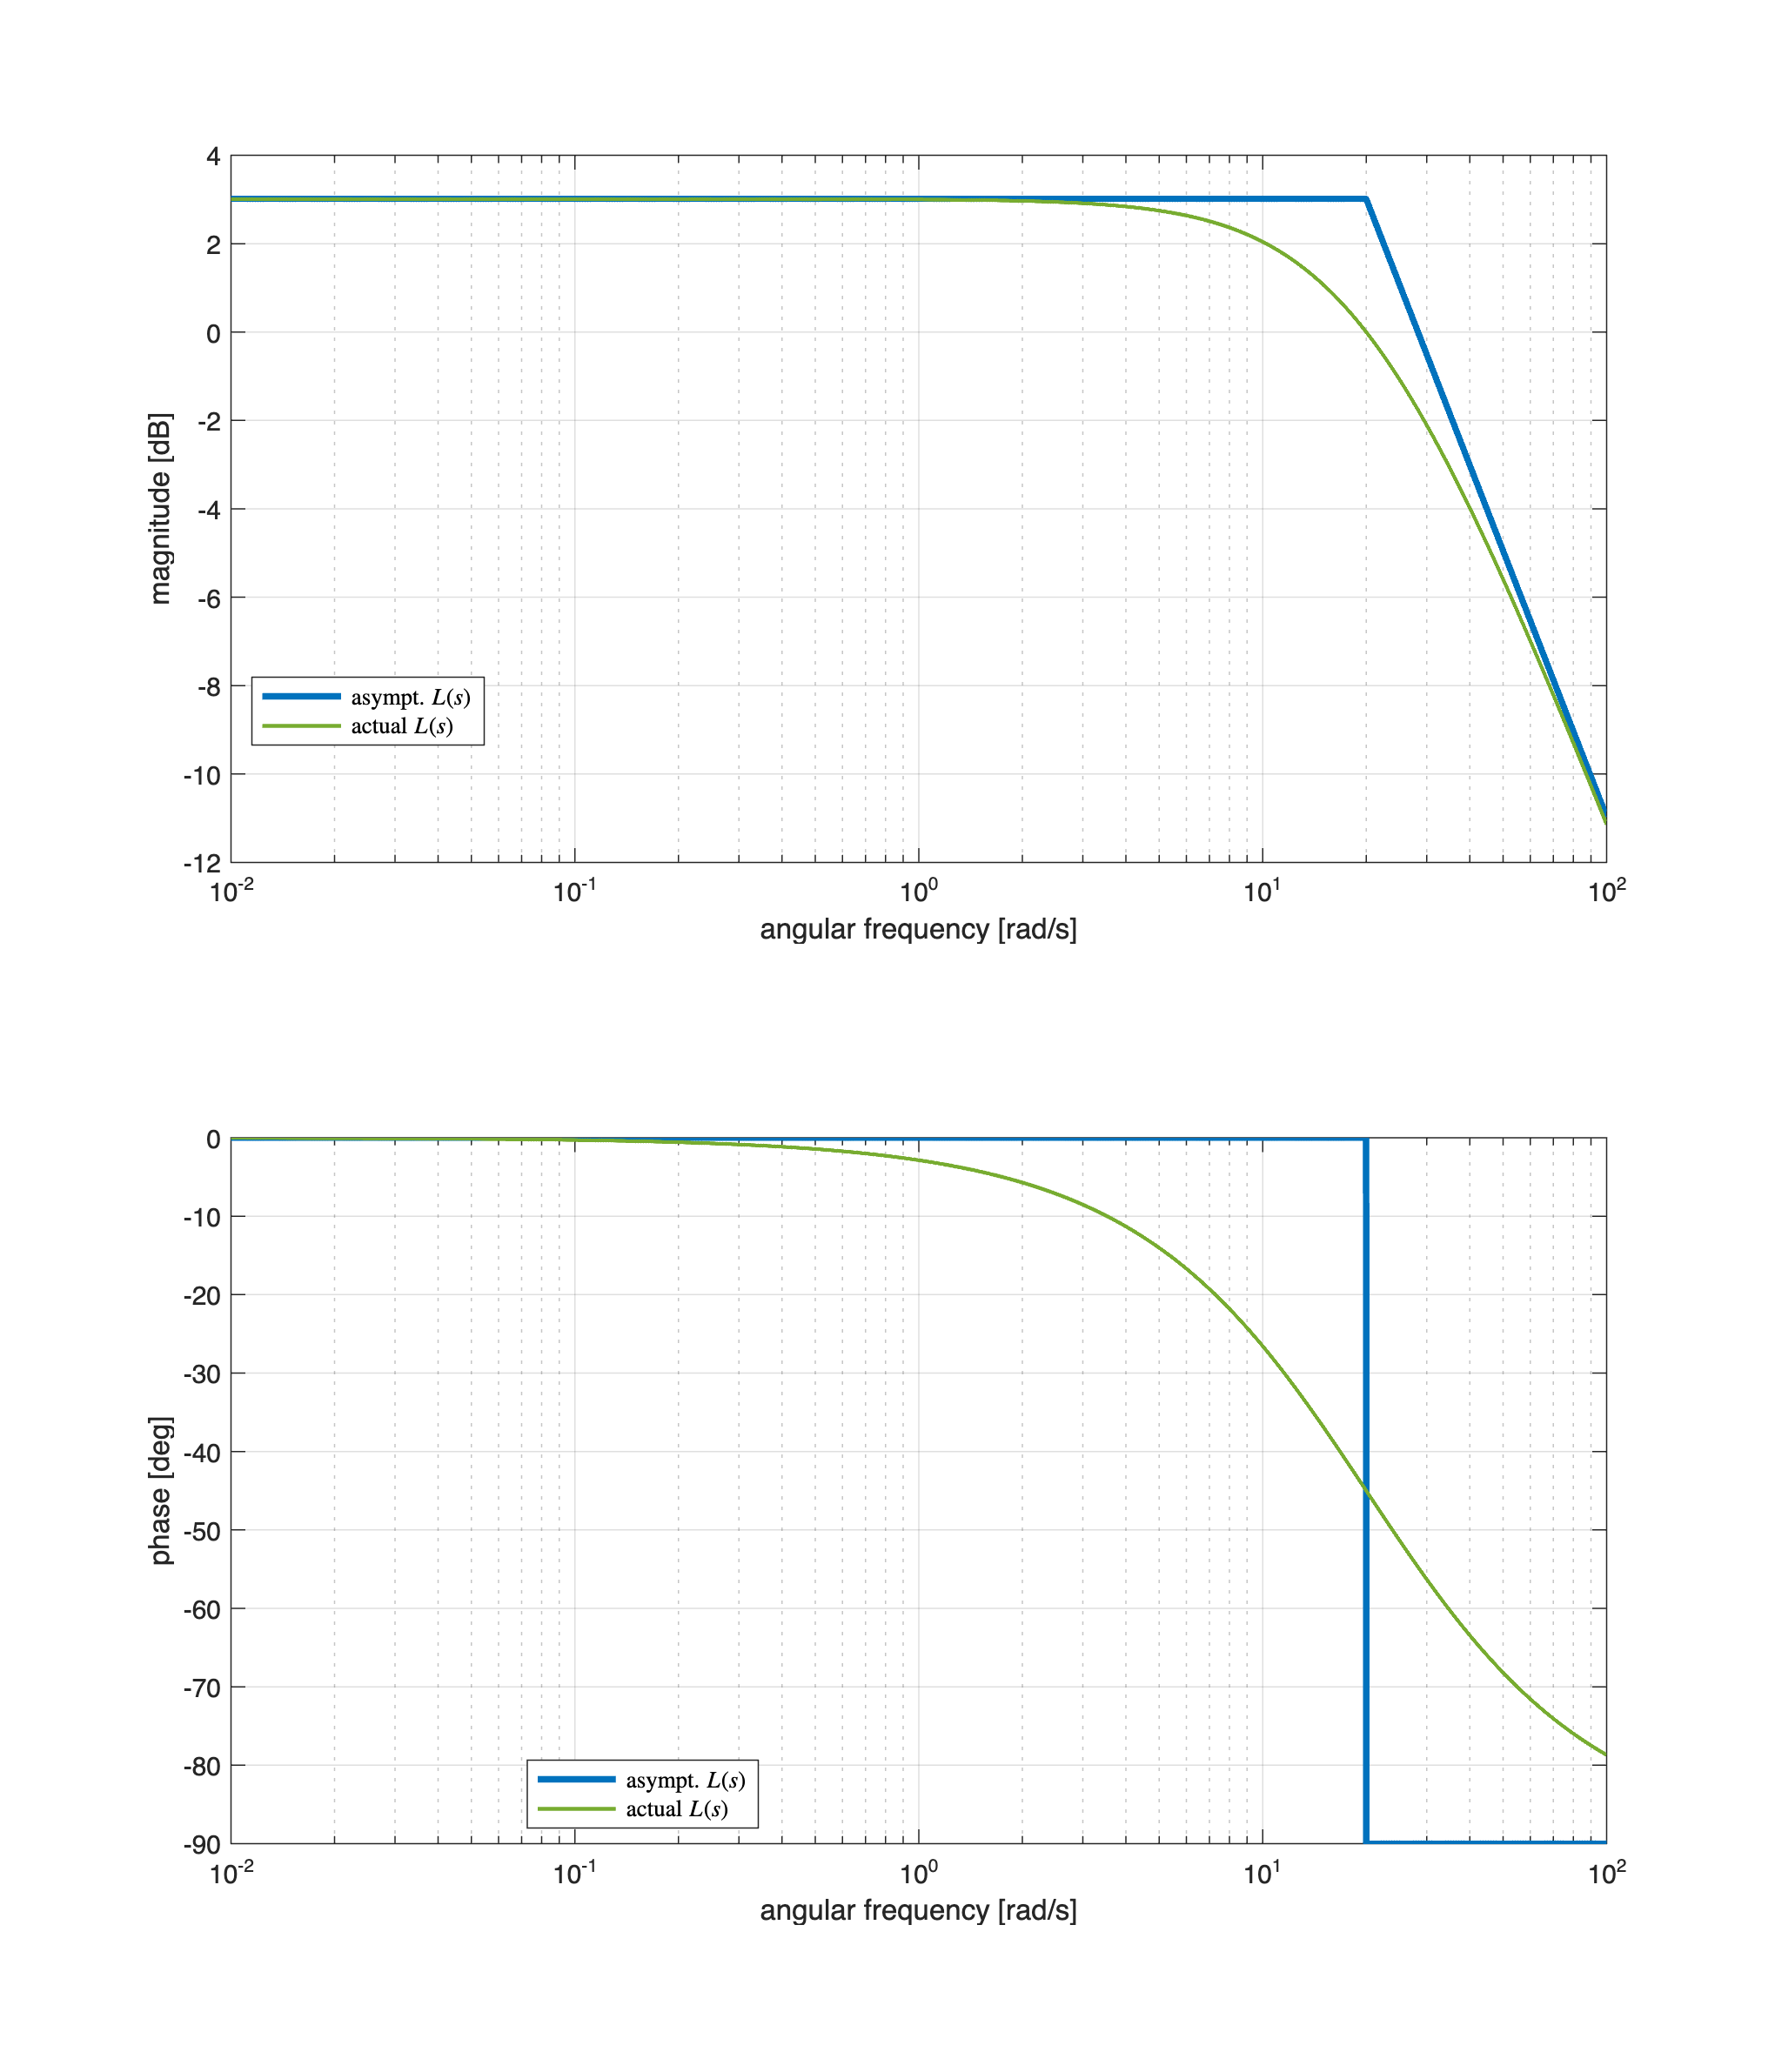


omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ls_new, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf);

legend(hax1, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2, 'asympt. $L(s)$', 'actual $L(s)$', ...
             'Interpreter', 'latex', ...
             'Location', 'best');

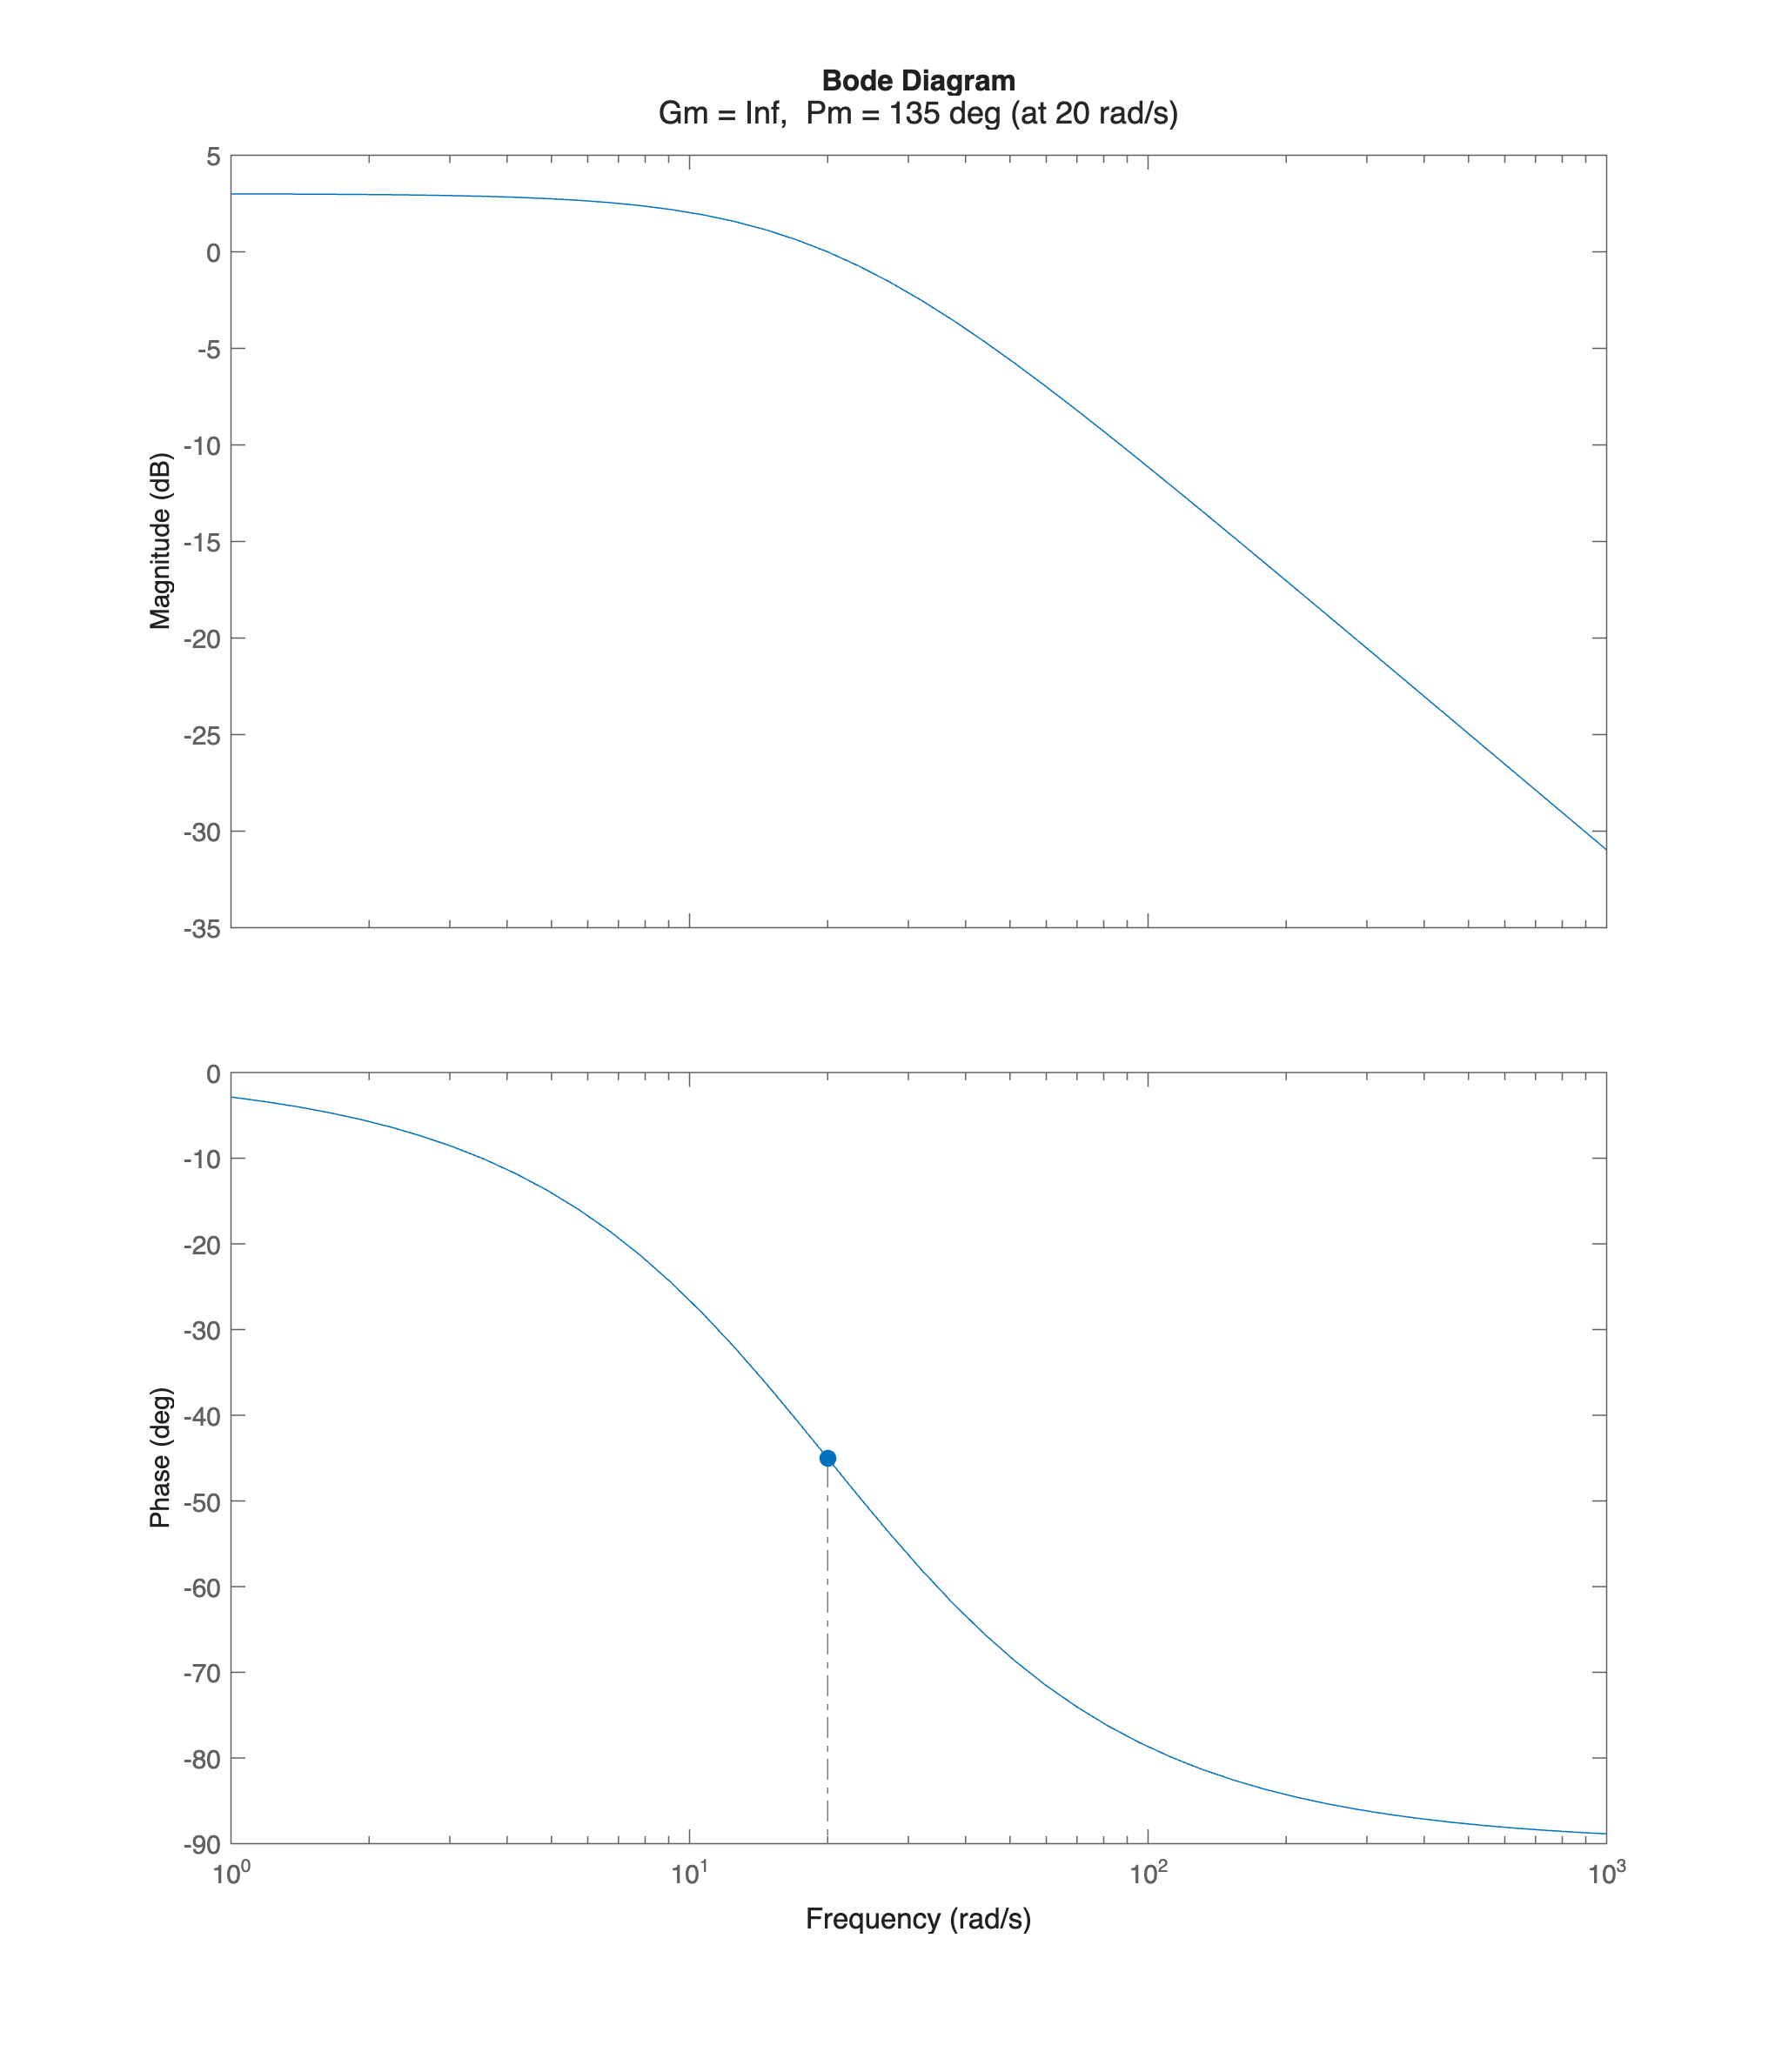

figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

margin(Ls_new)

The requirements are all met!

### **Fine Tuning using the Control System Designer App**

Let's analyse the control system performance using the controlSystemDesigner App:

controlSystemDesigner

Remember:

- configure the controlSystemDesigner App for a double loop design configuration;

- import the transfer function `Gs` of the inner plant $G_1(s)$;

- import the alredy designed transfer function `C2s` of the inner controller $C_2(s)$;

- finally import the transfer function `C1snew` of the outer controller $C_1(s)$

No need for further tuning.

**Designer App session file**: `FA_2025-02-03-ControlSystemDesignerSession.mat`